load('baseballstats.mat', 'Batting');

One of the first things that I want to do is divide the Batting table up by year. I use the findgroups() command. Here, I use [findgroups() and splitapply() ](http://blogs.mathworks.com/loren/2015/11/03/analyzing-baby-names-with-matlab-r2015b/#5c0cf125-9854-47d6-a1d3-e9cb0371cd01)to find the max number of doubles in each season over time

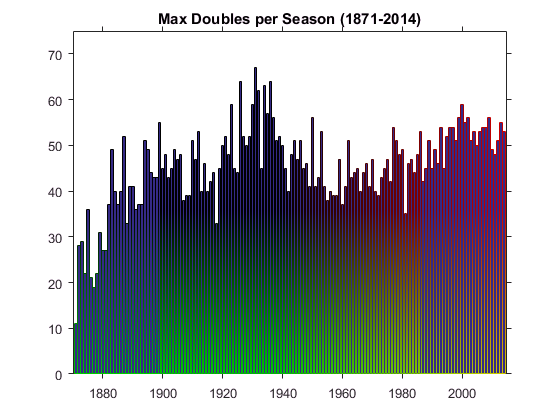

%% start batting analysis
Gyear = findgroups(Batting.yearID);
figure
bar(unique(Batting.yearID), splitapply(@max, Batting.x2B, Gyear));
title('Max Doubles per Season (1871-2014)')
ax = gca;
ax.TickDir = 'out';
ax.YLim = [0 75];
ax.XLim = [1870 2015];

Now I want to see if there is a correlation between the maximum number of doubles and the total number of hits

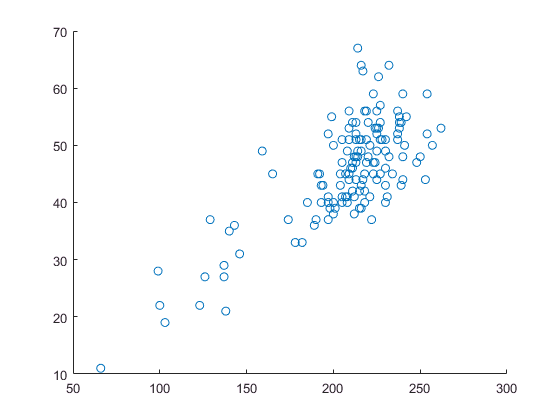

figure
scatter(splitapply(@max, Batting.H, Gyear), splitapply(@max, Batting.x2B, Gyear));

Now lets see if we can find Pete Rose

[Gplayer, players] = findgroups(Batting.playerID);
[~, idx] = max(splitapply(@sum, Batting.H, Gplayer));
players(idx)

ans =      rosepe01 
